syms W_11 W_12 W_21 W_22 x_1 x_2

w = [W_11, W_12;W_21, W_22]

$$w = \left(\begin{array}{cc} W_{11} & W_{12}\\ W_{21} & W_{22} \end{array}\right)$$

x = [x_1;x_2]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

w*x

$$ans = \left(\begin{array}{c} W_{11}\,x_{1}+W_{12}\,x_{2}\\ W_{21}\,x_{1}+W_{22}\,x_{2} \end{array}\right)$$

t = train_input(:,3)

t =    -0.6166
    0.6949


b = w*t-theta

b =     0.2396
    0.3614
    0.0922


b = 0;
for k=1:2
    b = b + w(3,k)*t(k);
end
b

b = 0.0922

V = tanh(b);
W(1)*V(1)+W(2)*V(2)+W(3)*V(3)

ans = 0.2178

W*V

ans = 0.2178

mu = randi([1,p]);
x_mu = train_input(:,mu); % randomly pick an input from training set
t_mu = target(mu);

% propagate forward
b_mu = w*x_mu-theta;
V = tanh(b_mu);  % activation function g = tanh()
B_mu = dot(W,V)-Theta;
Out = tanh(B_mu)

Out = -0.3204

diff(tanh(B_mu))


ans =

     []



syms x real
f = tanh(x);
diff(f)

Error using tanh
Not enough input arguments.

g = eval(subs(diff(f),0.03))

B_m = B_mu

B_m = -0.3321

t_m = target(mu);
Out_m = Out;
g_prime = eval(subs(diff(f), B_m))

g_prime = 0.8974

Delta_m = (t_m-Out_m) * g_prime;
delta_W = eta * Delta_m * V'

delta_W =     0.0105    0.0155    0.0041


W = W + delta_W

W =     0.2053    0.3980    0.5230


B = B_mu

B = -0.3321

t = target(mu);
g_prime_B = eval(subs(diff(f), B))

g_prime_B = 0.8974

Delta = (t - Out) * g_prime;
delta_W = eta * Delta * V';
W = W + delta_W;

% assume m=1
delta_w = zeros(size(w));
delta_theta = zeros(size(theta));
for n = 1:N
    x_n = x_mu(n);
    for m = 1:M
        b_m = b_mu(m);
        g_prime_b_m = eval(subs(diff(f), b_m));
        delta_m = Delta * W(1,m) * g_prime_b_m;
        delta_theta(m) = -eta * delta_m;
        delta_w(m,n) = -eta * delta_m * x_n;
    end
end

delta_theta =    -0.0075
         0
         0


delta_theta =    -0.0075
    0.0025
         0


delta_theta =    -0.0075
    0.0025
   -0.0108


delta_theta =    -0.0075
    0.0025
   -0.0108


delta_theta =    -0.0075
    0.0025
   -0.0108


delta_theta =    -0.0075
    0.0025
   -0.0108


w = w + delta_w

w =     0.1897   -0.4607
   -0.5509    0.8191
   -0.0140   -0.3600


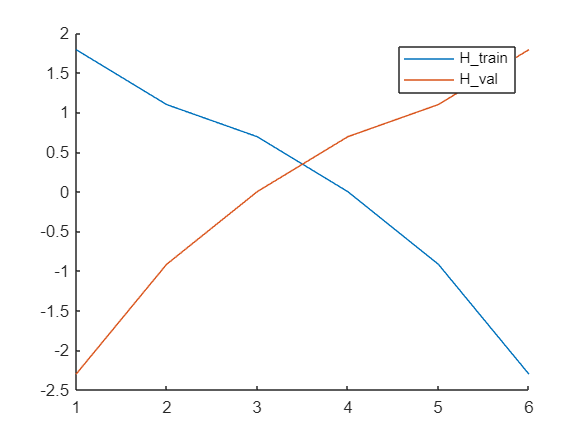

H=[];
H(end+1)=0.1;
H(end+1)=0.4;
H(end+1)=1;
H(end+1)=2;
H(end+1)=3;
H(end+1)=6;
H2 = H;
H = flip(H);
figure
hold on
plot(1:epoch_n,log(H))
plot(1:epoch_n,log(H2))
legend('H\_train','H\_val')
hold off